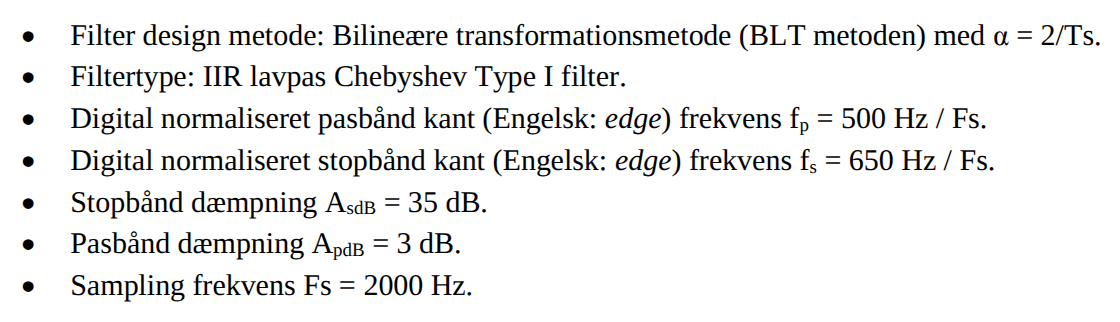

f_p = 500; f_s = 650; A_sdB = 35; A_pdB = 3; F_s = 2e3;

omega_p = (2*pi*f_p)/F_s; omega_s = (2*pi*f_s)/F_s;

Omega_p = 2*F_s*tan(omega_p/2)

Omega_p = 4.0000e+03

Omega_s = 2*F_s*tan(omega_s/2)

Omega_s = 6.5274e+03

nu = Omega_s/Omega_p

nu = 1.6319

n_cheb(A_sdB, A_pdB, nu)

e = 1.000000
n = 5.000000

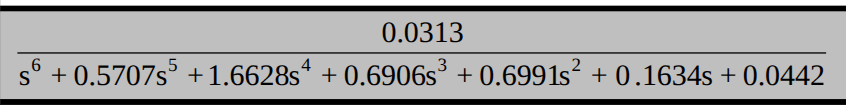

b_p = 0.0313; a_p = [1 0.5707 1.6628 0.6906 0.6991 0.1634 0.0442];
[bt, at] = lp2lp(b_p, a_p, Omega_p);
tf(bt,at)


ans =
 
                                     1.282e20
  -------------------------------------------------------------------------------
  s^6 + 2283 s^5 + 2.66e07 s^4 + 4.42e10 s^3 + 1.79e14 s^2 + 1.673e17 s + 1.81e20
 
Continuous-time transfer function.


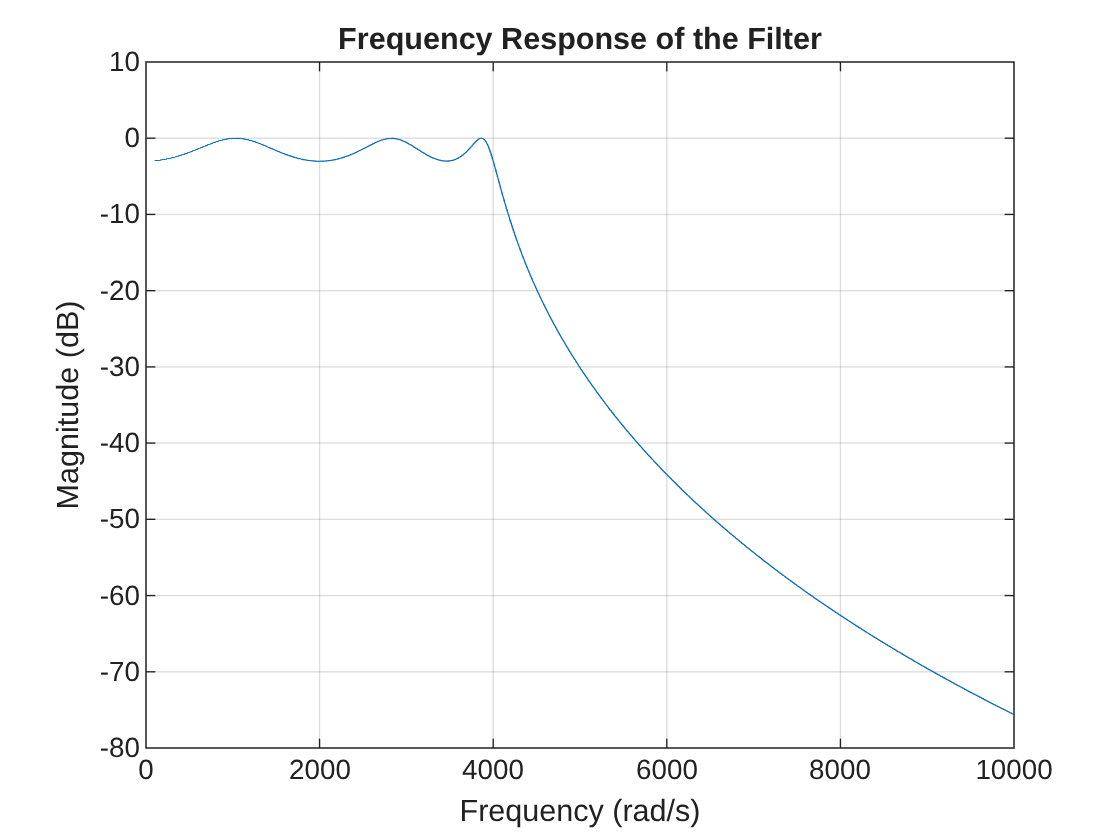

[h, w] = freqs(bt, at, 1024);

figure;
plot(w, 20*log10(abs(h)));
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Frequency Response of the Filter');
grid on;

[bd, ad] = bilinear(bt, at, F_s);

tf(bd, ad, 1/F_s, 'Variable', 'z^-1')


ans =
 
  0.006479 + 0.03888 z^-1 + 0.09719 z^-2 + 0.1296 z^-3 + 0.09719 z^-4 + 0.03888 z^-5 + 0.006479 z^-6
  --------------------------------------------------------------------------------------------------
           1 - 1.923 z^-1 + 3.084 z^-2 - 3.159 z^-3 + 2.422 z^-4 - 1.249 z^-5 + 0.4102 z^-6
 
Sample time: 0.0005 seconds
Discrete-time transfer function.


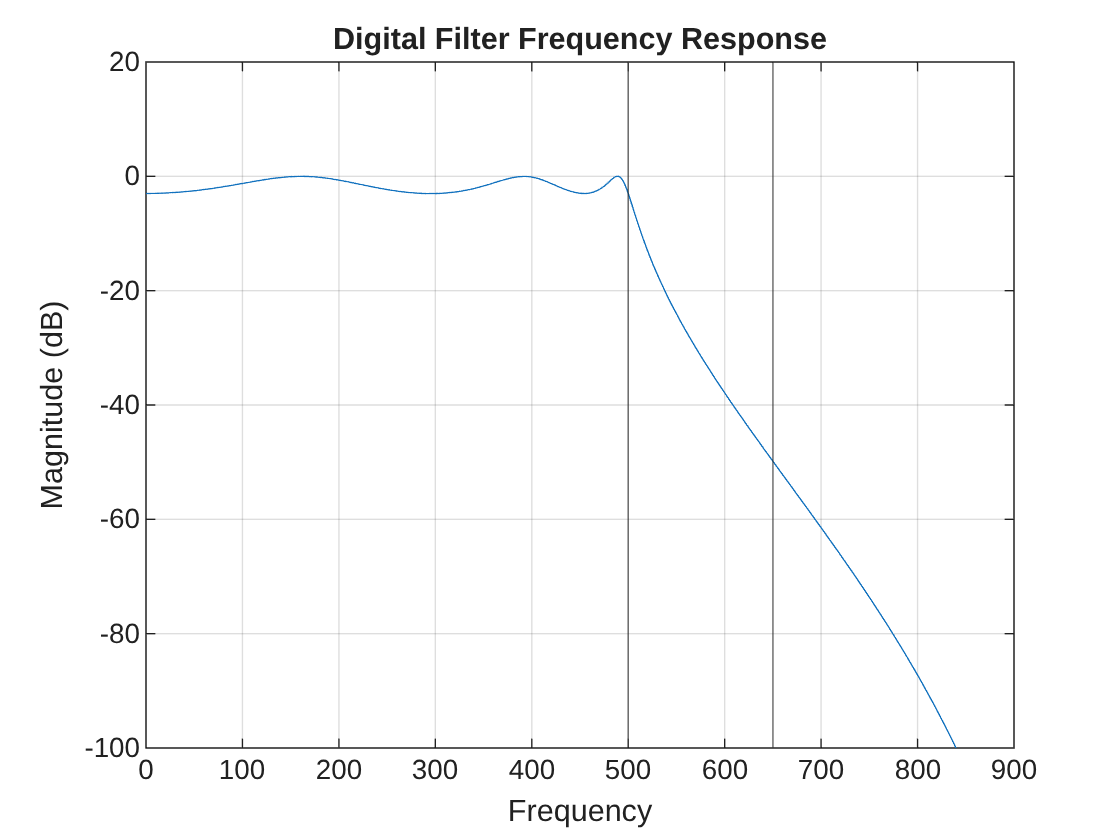


[H_d, f] = freqz(bd, ad, 1024, F_s);

figure;
plot(f, 20*log10(abs(H_d)));
xline([f_p f_s]);
ylim([-100 20]);
xlabel('Frequency');
ylabel('Magnitude (dB)');
grid on;
title('Digital Filter Frequency Response');